# Linear Control Design II - Group Work Problem Module 9

## **Description**

The dynamics of a wind turbine operating in the full load region reads


$$J_r\dot{\omega}_r = \frac{1}{2}\rho A R \mathrm{CP}(\beta,\lambda) \frac{v^2}{\lambda} - K_{d}\theta - B_{d}\left(\omega_r - \frac{\omega_g}{N_g}\right)$$



$$J_g\dot{\omega}_g = \frac{K_{d}}{N_g}\theta + \frac{B_{d}}{N_g}\left(\omega_r - \frac{\omega_g}{N_g}\right) - T_g$$



$$\dot{\theta} = \omega_r - \frac{\omega_g}{N_g}$$



$$y_1 = \omega_r$$



$$y_2 = P_e = \omega_g T_g$$


where all quantities of interest are defined Group work Module 1. Based on the provided Simulink model '*OpenLoopWindTurbineModel.slx*' and on the system parameter file 'OpenLoopWindTurbine_Parameters.mat' address the following problems.

## Problems

**P1    **Set the operating wind speed $v_{OP} = 20\,\mathrm{m/s}$ and compute analytically as well as numerically the operating point for the state vector $\mathbf{x}_{OP} = \left[\omega_{r,OP},\omega_{g,OP},\theta_{OP}\right]^\mathrm{T}$ and the input vector $\mathbf{u}_{OP} = \left[\beta_{OP},T_{g,OP}\right]^\mathrm{T}$.

Given condition:

Power on the generator and measuring low-speed shaft angular velocity


$$P_{e,OP}=5mW\\
\omega_{r,OP}=1.2671 \ rad/s
$$


At the operation point, $\mathbf{\dot{x}}_{OP} = \left[\dot\omega_{r,OP},\dot\omega_{g,OP},\dot{\theta}_{OP}\right]^\mathrm{T}=0$

From equations above, one can get


$$\omega_{g,OP}=\omega_{r,OP} \cdot N_{g}$$



$$T_{g,OP}=\frac{P_{e,OP}}{\omega_{g,OP}}$$



$$\theta_{OP}=T_{g,OP}\frac{N_g}{K_d}$$



$$CP(\beta_{OP},\lambda_{OP})=2\frac{K_d}{\rho AR} \frac{\lambda_{OP}}{v^2}\theta_{OP}$$



$$\lambda_{OP}=\frac{\omega_{r,OP}\cdot R}{v_{OP}}$$


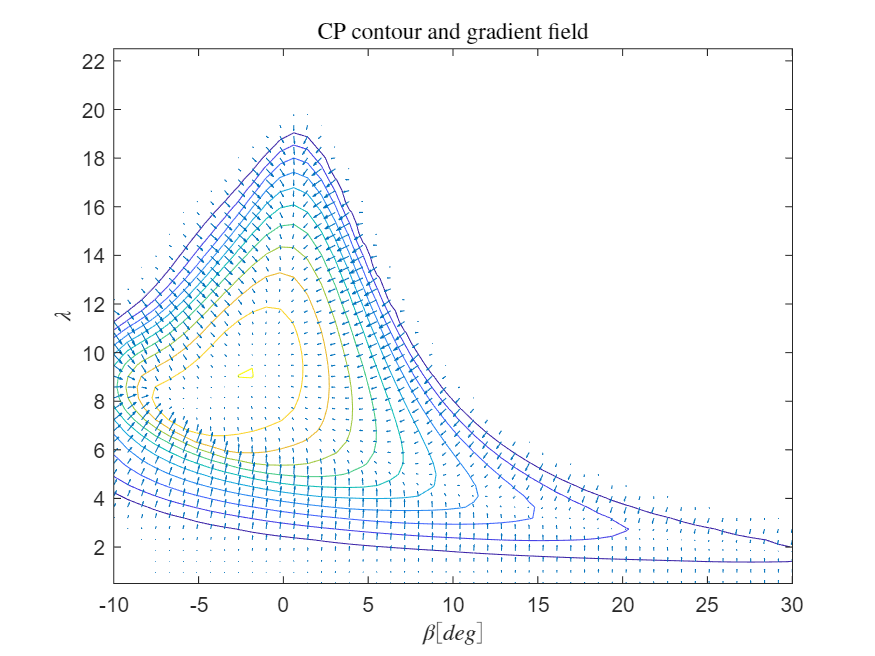

% For the numerical calculation of the operating point use the Matlab function trim
clear
close all
clc

% Analytical Derivation
load('OpenLoopWindTurbine_Parameters.mat');

% Display the CP function contour plot and gradient field, just to visualize it
[dCpBeta, dCpLambda] = gradient(CP);
figure(1)
contour(Pitch,Lambda,CP)
hold on
quiver(Pitch,Lambda,dCpBeta,dCpLambda)
xlabel('$\beta [deg]$','Interpreter','latex');
ylabel('$\lambda$','Interpreter','latex');
title('CP contour and gradient field', 'Interpreter','latex');
hold off

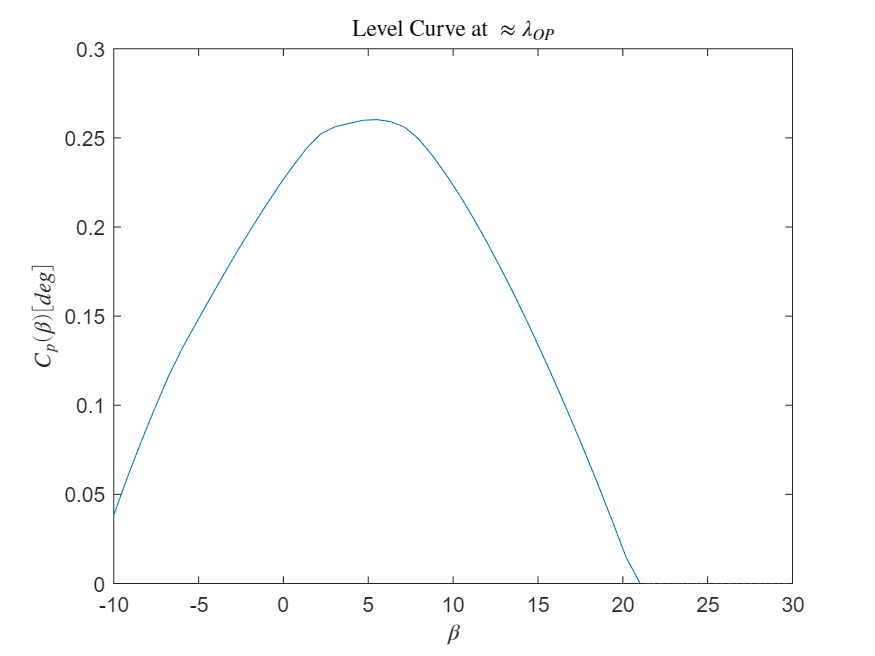

% The equations above tell that the only unknown parameter is beta
% wind speed
v_OP = 20; %[m/s]
% rotor anglular velocity
omega_r_OP = 1.2671; %[rad/s]
% generator power
Pe_OP = 5e6; % [W]

% generator angular velocity
omega_g_OP = Ng * omega_r_OP;
% torque on generator
Tg_OP = Pe_OP/omega_g_OP;
% torsional angle, angle difference between low-speed and high-speed shaft
theta_OP = Tg_OP*Ng/Kd;

% Analytically only an approximate beta can be found
% required tip-speed ratio,lambda_OP
LBD_OP = omega_r_OP*R/v_OP; 
Diff = Lambda0-LBD_OP;
% Find the closeset lambda in the dataset
[~,Index_LBD_OP] = min(abs(Diff));
% find the corresponding CP values given lambda_OP
CP_fun_beta = CP0(Index_LBD_OP,:);

figure(2)
plot(Pitch0, CP_fun_beta)
xlabel('$\beta$','interpreter','latex')
ylabel('$C_p(\beta) [deg]$','interpreter','latex')
title('Level Curve at $\approx \lambda_{OP}$','Interpreter','latex')

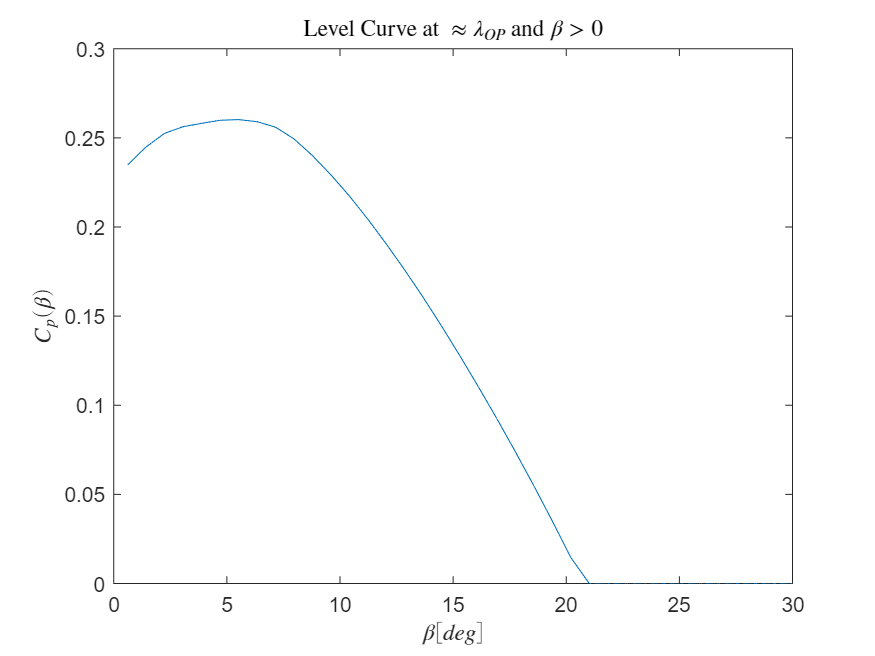

% Exclude CP values with negative beta. Negative value mean turbin is stalled.
i_beta_pos = Pitch0>0;
figure(3)
plot(Pitch0(i_beta_pos),CP_fun_beta(i_beta_pos))
title('Level Curve at $\approx \lambda_{OP}$ and $\beta > 0$','Interpreter','latex')
xlabel('$\beta [deg]$','interpreter','latex')
ylabel('$C_p(\beta)$','interpreter','latex')

Since 


$$CP(\beta_{OP},\lambda_{OP})=2\frac{K_d}{\rho AR} \frac{\lambda_{OP}}{v^2}\theta_{OP}$$


% Based on the origin euqation
CP_OP_value1 = 2*Kd/(rho_air*A*R)*lambda_OP/v_OP^2*theta_OP

CP_OP_value1 = 0.0781

% Based on substituation operations
CP_OP_value = 2*omega_r_OP*Ng/(rho_air*A*v_OP^3)*Tg_OP;
% find closest CP value to the operation point
Diff1 = CP_fun_beta(i_beta_pos)-CP_OP_value;
[~,Index_Beta_OP] = min(abs(Diff1));
% find the first positive beta index
one = find(i_beta_pos == 1); 
Beta_OP_deg = Pitch0(one(1)+Index_Beta_OP) % [deg]

Beta_OP_deg = 18.5714

Beta_OP_rad = Beta_OP_deg * pi/180

Beta_OP_rad = 0.3241

So far, the operation point is not exaclty determined because of $\beta_{OP}$. To exacly determine the operating point, one has to trim the system.

The **analytical **operation point is:

xOP_0 = [omega_r_OP;omega_g_OP;theta_OP]

xOP_0 =     1.2671
  122.9087
    0.0045


uOP_0 = [Beta_OP_rad;Tg_OP]

uOP_0 = 	1.0e+04 *

    0.0000
    4.0681


yOP_0 = [omega_r_OP;Pe_OP]

yOP_0 = 	1.0e+06 *

    0.0000
    5.0000


The numerical operational point is:

% x0=xOP_0;
x0=[1 120 0.03]';
format short g
%[xOP,uOP] = trim('MyOpenLoopWindTurbineModelTrim2015a',xOP_0,uOP_0,yOP_0)
[xOP,uOP] = trim('MyOpenLoopWindTurbineModelTrim2015a',x0,uOP_0,yOP_0,[],[],[1 1])

xOP =     1.2671
  122.9087
    0.0045


uOP =     0.0000
    4.0681


**P2    **Linearize analytically and numerically the nonlinear wind turbine model around the operaitng point determined in **P1**.

% For the numerical linearization use the Matlab function linmod
x0 = xOP; % update initial conditions
uOPDist = [uOP;v_OP]; % include the disturbence into input vector
[Aa,Bb,Cc,Dd] = linmod('MyOpenLoopWindTurbineModeLinmod',xOP,uOPDist);
Aa

Aa =    -0.0000    0.0000   -0.0015
    0.0120   -0.0001    1.6747
    0.0001   -0.0000         0


Bv = Bb(:,3)

Bv =     0.0209
         0
         0


Bb = Bb(:,1:2)

Bb =    -1.1066         0
         0   -0.0019
         0         0


Cc = Cc([1 4],:)

Cc =     1.0000         0         0
         0    0.0407         0


Dd = Dd([1 4],1:2)

Dd =          0         0
         0    0.1229


**P3    **Through simulation compare the state and output responses for step changes in the operating wind speed. Perform simulations for $\Delta v_{OP} = \pm0.5\,\mathrm{m/s}$ and for $\Delta v_{OP} = \pm2\,\mathrm{m/s}$ and discuss how well the linear model approximate the nonlinear dynamics.

Rember when setting up the Simulink model, the input should be reset to fullfill the problem requirements, such as

v_OP block should be set as: v_OP+Dv_OP

beta_OP block should be: uOP(1)+DU(1)

Tg_OP block should be: uOP(2)+DU(2)

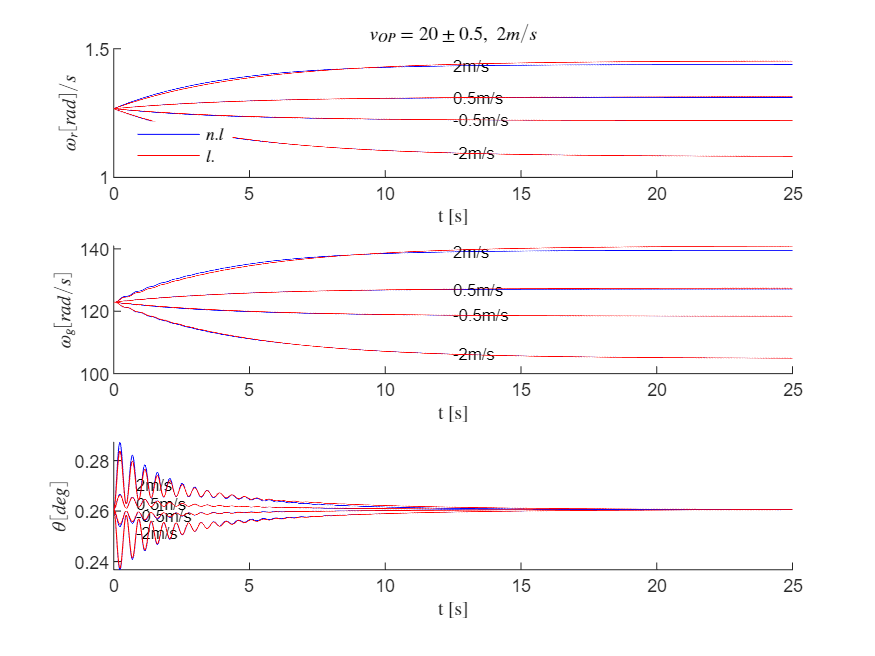

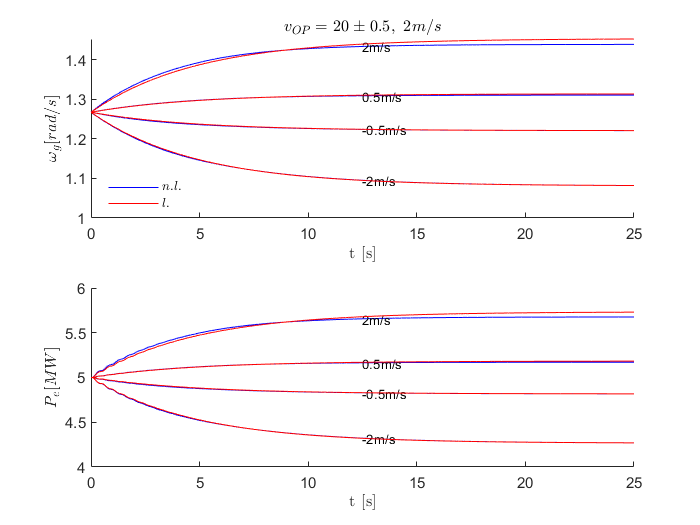

% Perform simulations around the operating point and plot the state and output responses
DU = [0;0];
TIME_SIM = 25;
for Dv_OP = [-0.5 0.5 -2 2]
    figure(4)
    sim('MyOpenLoopWindTurbineModeLvsNL.slx')
    %sim('Module 9 Solution\OpenLoopWindTurbineModelLVsNL2015a.slx')
    %sim('testNLvsL.slx')
    % non-linear states and output
    x1 = yout(:,1);
    x2 = yout(:,2);
    x3 = yout(:,3);
    y1 = yout(:,1);
    y2 = yout(:,4);

    % linear states and output
    x1l = yout(:,5);
    x2l = yout(:,6);
    x3l = yout(:,7)*180/pi;
    y1l = yout(:,8);
    y2l = yout(:,9);

    %  wr
    subplot(3,1,1)
    hold on
    plot(tout,x1,'b'); % nonlinear x1(wr) results
    text(tout(floor(end/2)),x1(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
    plot(tout,x1l+xOP(1),'r');% linear x1(wr) results remember to add x1_OP
    leg1 = legend('$n.l$','$l.$','Location','best');
    set(leg1,'Interpreter','latex');
    set(leg1,'Fontsize',8);
    legend boxoff
    xlabel('t [s]','Interpreter','latex')
    ylabel('$\omega_r [rad]/s$','Interpreter','latex')
    title('$v_{OP} = 20 \pm 0.5, \ 2 m/s$','Interpreter','latex')
    hold off
    
    % wg
    subplot(3,1,2)
    hold on
    plot(tout,x2,'b')
    text(tout(floor(end/2)),x2(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
    plot(tout,x2l+xOP(2),'r')
    xlabel('t [s]','Interpreter','latex')
    ylabel('$\omega_g [rad/s]$','Interpreter','latex')
    hold off
    
    % theta
    subplot(3,1,3)
    hold on
    plot(tout,x3,'b')        
    text(tout(floor(end/30)),x3(floor(end/30)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
    plot(tout,x3l+xOP(3)*180/pi,'r')
    xlabel('t [s]','Interpreter','latex')
    ylabel('$\theta [deg]$','Interpreter','latex')
    hold off

    % y1-wr
    figure(5)
    subplot(2,1,1)
    hold on
    plot(tout,y1,'b')
    text(tout(floor(end/2)),y1(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
    plot(tout,y1l+xOP(1),'r')
    leg1 = legend('$n.l.$','$l.$','location','best');
    set(leg1,'Interpreter','latex');
    set(leg1,'FontSize',8);
    legend boxoff
    xlabel('t [s]','Interpreter','latex')
    ylabel('$\omega_g [rad/s]$','Interpreter','latex')
    title('$v_{OP} = 20 \pm 0.5, \ 2  m/s$','Interpreter','latex')        
    hold off
       
    % y2-Pe
    subplot(2,1,2)
    hold on
    plot(tout,y2,'b')
    text(tout(floor(end/2)),y2(floor(end/2)),[num2str(Dv_OP) 'm/s'],'FontSize',8)
    plot(tout,y2l+Pe_OP/1e6,'r')
    xlabel('t [s]','Interpreter','latex')
    ylabel('$P_e [MW]$','Interpreter','latex')
    hold off
end

The model respond similarly to the variation in the wind speed though the larger the variation the less accurate the linear model compared to the non linear one.

**P4    **Sweep the wind speed in the range $v_{OP} \in \left[18, 25\right] \, \mathrm{m/s}$ and assess how the eigenvalues of the linear model vary in relation to changes in the operating wind speed. What conclusion can be reached about the stability of the origin of the linear model?

% For each operating wind speed in the given range the system dynamical matrix A needs to be recomputed.
v_OP_step = 0.2;
vVector = 18:v_OP_step:25;
ev = zeros(length(vVector),3);
for i=1:length(vVector)
    v_OPn = 18+(i-1)*v_OP_step;
    xOP_0 = [omega_r_OP;omega_g_OP;theta_OP];
    uOP_0 = [Beta_OP_rad;Tg_OP;v_OPn];
    yOP_0 = [omega_r_OP;omega_g_OP;theta_OP;Pe_OP];

    x0 = xOP_0; % Integrator initial conditions
    format short g
   [xOP,uOP] = trim('MyOpenLoopWindTurbineModeLinmod',xOP,uOP_0,yOP_0,[],[],[1 1]);
   [Aol,~,~,~] = linmod('MyOpenLoopWindTurbineModeLinmod',xOP,uOP);
   ev(i,:) = eig(Aol);
end

For different v_OP, the eigenvalues are calculated like this

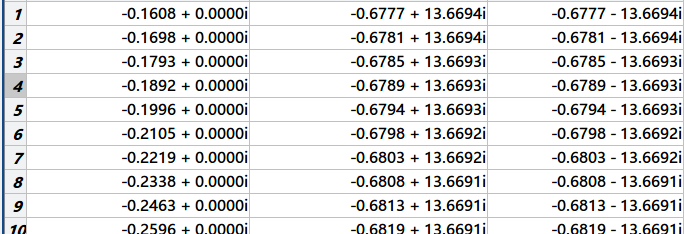

Can be seen that the imaginary part is always the same. Hence only the real part will be plotted.

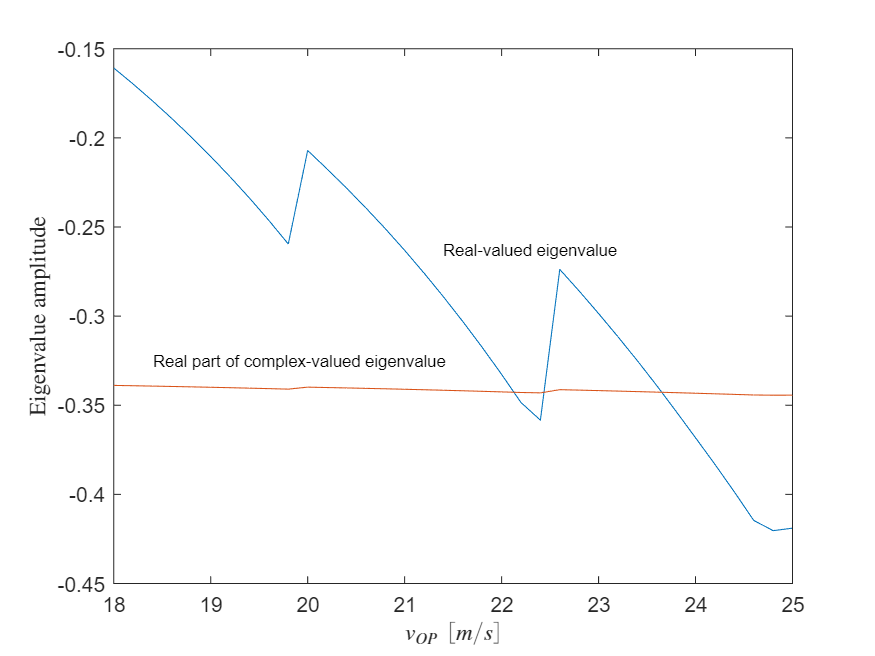

figure(6)
plot(vVector,ev(:,1))
hold on
plot(vVector,real(ev(:,2))*0.5)
xlabel('$v_{OP} \ [m/s]$','interpreter','latex')
ylabel('Eigenvalue amplitude','Interpreter','latex')
text(vVector(floor(end/2)),ev(floor(end/2),1)/1.1,'Real-valued eigenvalue','FontSize',8)
text(vVector(floor(end/10)),ev(floor(end/2),2)/2.1,'Real part of complex-valued eigenvalue','FontSize',8)

From the plot, we can conclude that the real part of each eigenvalues are located on the left half plane, thus the system is always stable under every possible v from 18 to 25. Also, as the wind speed goes larger, the poles go far away from the imaginary axis.  

**P5   **Set the wind speed at $v_{OP} = 20\,\mathrm{m/s}$ and compute the modal matrix. Write the state response as the linear combination of the eignemodes of the system and determine which eigenmode is dominant in each of the state variables.

% The modal matrix can be found by using the Matlab function eig
[M,E] = eig(Aa);
% time constants
lbd = diag(E)

lbd =   -0.2071 + 0.0000i
  -0.6797 +13.6692i
  -0.6797 -13.6692i


tau = -1./lbd(imag(lbd)==0) % find real eigenvalues

tau =        4.8291


% natural frequencies and damping ratios
wn = sqrt(real(lbd(2))^2+imag(lbd(2))^2)

wn =        13.686


z = - real(lbd(2))/wn

z =      0.049661


% format long
% Easy way to do
% [wn,zeta]=damp(Aa)
lbd = diag(lbd);
[M,V] = cdf2rdf(M,lbd)

M =    -0.0103   -0.0012   -0.0000
   -0.9999    1.4142         0
    0.0000    0.0001    0.0012


V =    -0.2071         0         0
         0   -0.6797   13.6692
         0  -13.6692   -0.6797


$\omega_{r}$ is influenced mainly bt the first eigenmode

**P6**    Determine a suitable sampling time for the linear system and discretize the linear model. Compute the eigenvalues of the discrete time linear model and use Frobenius theorem to show the equivalence with the eigenvalues of the continuous time linear system.

% To discretize the continuous time linear system use the Matlab function c2d
T = 2*pi/wn;
if T<tau(1)
    Ts = tau(1)/10;
else
    Ts = T/10
end
[Ff,Gg] = c2d(Aa,Bb,Ts)

Ff =     0.8862    0.0002   -0.2381
   21.0086    0.6916  276.0987
    0.0162   -0.0002    0.6953


Gg =    -0.4701   -0.0000
  -43.8580   -0.0001
   -0.0013    0.0000


lbd_d = eig(Ff)

lbd_d =    0.9048 + 0.0000i
   0.6841 + 0.2251i
   0.6841 - 0.2251i


lbd_d_calc=exp(Ts*lbd)

lbd_d_calc =    0.9048 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.6841 + 0.2251i   1.0000 + 0.0000i
   1.0000 + 0.0000i   1.0000 + 0.0000i   0.6841 - 0.2251i
